# Assignment #2

1) How would you use the colon operator to generate the following vector: *[9 7 5 3 1]*?

[9:-2:1]

ans =      9     7     5     3     1


2) a) Use Matlab's *sum()* command and vector colon notation to construct the sum of the first 1000 natural numbers.

sum(1:1000)

ans = 500500

    b) Use Matlab's *sum()* command and vector colon notation to find the sum of the first 1,000 odd positive integers.

sum(1:2:2000)

ans = 1000000

3) Let $v=[1,3,5,7], w=[5,2,5,4]$. Think about the output of each of the following commands; write down by hand what you think the answer will be. Next, run the commands in Matlab and check your results. Did they match? $v>w,\ v>=w,\ v<=w,\ v<w,\ v==w,\ v\sim=w$.

v = [1 3 5 7]

v =      1     3     5     7


w = [5 2 5 4]

w =      5     2     5     4


v > w

ans = 1×4 logical array
   0   1   0   1


v >= w

ans = 1×4 logical array
   0   1   1   1


v <= w

ans = 1×4 logical array
   1   0   1   0


v < w

ans = 1×4 logical array
   1   0   0   0


v == w

ans = 1×4 logical array
   0   0   1   0


v ~= w

ans = 1×4 logical array
   1   1   0   1


% I have some experience with array programing languages (R and APL in
% particular), so these were what I expected them to be

4) The empty vector is denoted *[ ]*. This can be used to delete elements of a vector. Create a vector *v* of length 5 and delete the first element by using *v(1)=[ ]*. What happens when you evaluate v(1)? What about v(5)?

v = 1:5

v =      1     2     3     4     5


v(1) = []; % set first element to empty vector
v(1) % second element is now first

ans = 2

% v(5) - error


5) Read the documentation for the *primes()* and *isprime()* commands. 

a) Find a prime n so that  primes(n)=100. 

% that's not possible
% if the question meant such that length(primes(n)) = 100, then
length(primes(541)) 

ans = 100

b) Find the sum of the first 100 primes. 

sum(primes(541))

ans = 24133

c) Create a vector *gaps* of prime gaps (difference bewteen successive primes) for all primes less than or equal to 10,000,000. What is the length of *gaps?*Find the maximum and minimum of the entries.

vPrime = primes(10000000)

vPrime =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97   101   103   107   109   113   127   131   137   139   149   151   157   163   167   173   179   181   191   193   197   199   211   223   227   229


n = length(vPrime)

n = 664579

gaps = vPrime(2:n) - vPrime(1:(n - 1))

gaps =      1     2     2     4     2     4     2     4     6     2     6     4     2     4     6     6     2     6     4     2     6     4     6     8     4     2     4     2     4    14     4     6     2    10     2     6     6     4     6     6     2    10     2     4     2    12    12     4     2     4


length(gaps) % length is one less than length of 'gaps'

ans = 664578

max(gaps)

ans = 154

min(gaps)

ans = 1

d) Read about the command *unique* and apply it to find out what numbers arise as prime gaps in *gaps.* Plot a histogram using the command *histogram.*

unique(gaps)

ans =      1     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


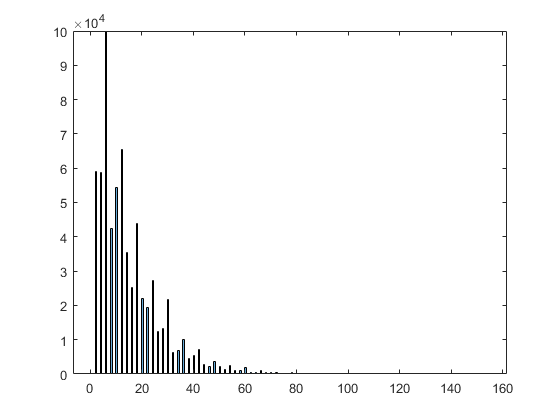

histogram(gaps)

6) Another handy function is *linspace(x,y,n)* which gives a row vector with *n* elements linearly (evenly) spaced between *x* and *y*.

a)  Using this function, make a row vector of 100 evenly spaced elements between 1 and 0.

linspace(1, 0) % 100 points is the default

ans =     1.0000    0.9899    0.9798    0.9697    0.9596    0.9495    0.9394    0.9293    0.9192    0.9091    0.8990    0.8889    0.8788    0.8687    0.8586    0.8485    0.8384    0.8283    0.8182    0.8081    0.7980    0.7879    0.7778    0.7677    0.7576    0.7475    0.7374    0.7273    0.7172    0.7071    0.6970    0.6869    0.6768    0.6667    0.6566    0.6465    0.6364    0.6263    0.6162    0.6061    0.5960    0.5859    0.5758    0.5657    0.5556    0.5455    0.5354    0.5253    0.5152    0.5051


b) Using vectorization, estimate the limit $\lim_{x\rightarrow 0}\frac{\sin(x)}{x}$.

space = linspace(0, 1);
format long
sin(space) ./ space

ans =                  NaN   0.999982995019241   0.999931981117973   0.999846961419143   0.999727941127409   0.999574927528764   0.999387929990002   0.999166959958035   0.998912030959060   0.998623158597574   0.998300360555236   0.997943656589577   0.997553068532563   0.997128620289004   0.996670337834807   0.996178249215091   0.995652384542139   0.995092775993202   0.994499457808161   0.993872466287025   0.993211839787293   0.992517618721155   0.991789845552550   0.991028564794073   0.990233823003731   0.989405668781553   0.988544152766050   0.987649327630528   0.986721248079250   0.985759970843452   0.984765554677216   0.983738060353186   0.982677550658148   0.981584090388457   0.980457746345319   0.979298587329928   0.978106684138463   0.976882109556928   0.975624938355857   0.974335247284876   0.973013115067116   0.971658622393484   0.970271851916793   0.968852888245749   0.967401817938800   0.965918729497834   0.964403713361745   0.962856861899861   0.961278269405219   0.959668032

c) Generate a list of 10,000 random numbers uniformly between 0 and 1. Approximate the average value of $\frac{1}{x+1}$ on $[0,1]$. Does this answer make sense? (Hint: use Calculus).

randArr = rand(1, 100000)

randArr =    0.058349259399840   0.718287058855217   0.390088322428128   0.271341065885992   0.721784882919507   0.701008318304335   0.552526215342755   0.461349865016234   0.676419689928689   0.072542320249357   0.386888238833257   0.979035233850091   0.300057463220462   0.329657479850589   0.788420180343650   0.823931536835141   0.301831248982197   0.344071631250884   0.497750550668376   0.537480432988291   0.018592383948609   0.341996855843962   0.943848589836155   0.157885387210885   0.920093740080286   0.188375721379564   0.242189791887004   0.611825263687952   0.874116349981890   0.845138714187575   0.688223351657561   0.160750943777124   0.769371875550187   0.508543544075708   0.098928740797395   0.448294349333963   0.339572089582889   0.268487365891693   0.489493357121891   0.550464431489522   0.958694942633028   0.922247197695988   0.003163567353858   0.996391600911556   0.568155736935423   0.051674466594847   0.788489553670698   0.479460251215057   0.716790019136639   0.59169

average = sum(1 ./ (randArr + 1)) ./ 100000

average =    0.693064142775357


% yes, this makes sense since the average should be ln(2) - ln(1)

Matrices 

7) Create a *5x8* matrix of all zeros and store it in a variable. Now replace the second row in the matrix with all 4's and the first column with the entries *[2 4 6 8 10]*.

A = zeros(5, 8)

A =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


A(2, :) = 4

A =      0     0     0     0     0     0     0     0
     4     4     4     4     4     4     4     4
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


A(:, 1) = 2:2:10 

A =      2     0     0     0     0     0     0     0
     4     4     4     4     4     4     4     4
     6     0     0     0     0     0     0     0
     8     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0


8) Create a *100 x 100* matrix of random reals in the range from -10 to 10. Get the sign of every element. What percentage of the elements are positive?

format short
B = rand(100, 100) * 20 - 10; % 100x100 matrix of [-10, 10]
Bsign = (sign(B) + 1) ./ 2; % signs: 0 for negative, 1 for positive to make calculation easier
p = sum(sum(Bsign)) ./ (100.^2) % calculates proportion of 1s in matrix

p = 0.5047

9) In the following exercises, predict the output of the given command, then validate your response with the appropriate Matlab command. Use *A=magic(5)*.


$$A>14$$



$$A<=12$$



$$(A>3)\ \&\ (A<=20)$$



$$(A<5)\ \&\ (A>=21)$$



$$\sim (A<=6)$$



$$(A>6)\ \&\ \sim (A>8)$$


A = magic(5) % 5x5 magic square

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


A > 14

ans = 5×5 logical array
   1   1   0   0   1
   1   0   0   0   1
   0   0   0   1   1
   0   0   1   1   0
   0   1   1   0   0


A <= 12

ans = 5×5 logical array
   0   0   1   1   0
   0   1   1   0   0
   1   1   0   0   0
   1   1   0   0   1
   1   0   0   1   1


(A > 3) & (A <= 20)

ans = 5×5 logical array
   1   0   0   1   1
   0   1   1   1   1
   1   1   1   1   0
   1   1   1   0   0
   1   1   0   0   1


(A < 5) & (A >= 21)

ans = 5×5 logical array
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0


~(A <= 6)

ans = 5×5 logical array
   1   1   0   1   1
   1   0   1   1   1
   0   0   1   1   1
   1   1   1   1   0
   1   1   1   0   1


(A > 6) & ~(A > 8)

ans = 5×5 logical array
   0   0   0   1   0
   0   0   1   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0


% all what I expected
